# 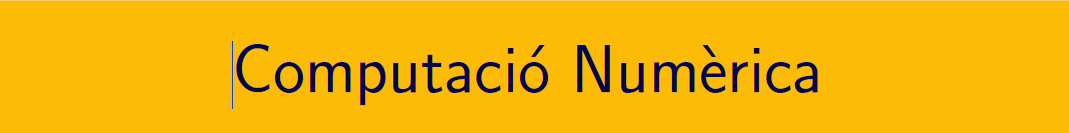

`===================================================================================`

# `Pràctica 14. Equacions diferencials ordinàries (IV).`

`Document preparat per M. Àngela Grau Gotés - 29 de maig de 2023`

## `Sistemes d'equacions diferencials de primer ordre`

## `Exercici  `$y^{\prime\prime}(t)+4y(t)=0\,,\quad y(0)=2,\  y^{\prime}(0)=8,\quad 0\leq t\leq 4\,.$

`Reducció a un sistema d'equacions de primer ordre`

`El canvi seria, `$u_1(t) = y(t)\,,\quad u_2(t) = y{^\prime}(t)$` i el sistema de primer ordre és `


$$	\left\lbrace \begin{array}{rcl}
			u_1^{\prime}(t)&=&u_2(t)\,, 	\\   
u_2^{\prime}(t)&=&-4u_1(t)\,, \\
u_1(0) &=& 2\,,\\
u_2(0) &=& 8\,.
\end{array}\right. $$


`Solució analítica`

clearvars
syms t y(t) z(t)
eqns = [diff(y,t) == z, diff(z,t) == -4*y];
conds = [y(0) == 2, z(0)==8];
[ySol(t),zSol(t)] = dsolve(eqns,conds);

`La solució es pot respresentar a l'interval [0,4]`

Y(t) = simplify(ySol(t)), Z(t) = simplify(zSol(t))

$$Y(t) = 2\,\cos\left(2\,t\right)+4\,\sin\left(2\,t\right)$$

$$Z(t) = 8\,\cos\left(2\,t\right)-4\,\sin\left(2\,t\right)$$

## `Solucions aproximades numèricament O(h)`

- `Mètode Euler (sistemes equacions)`

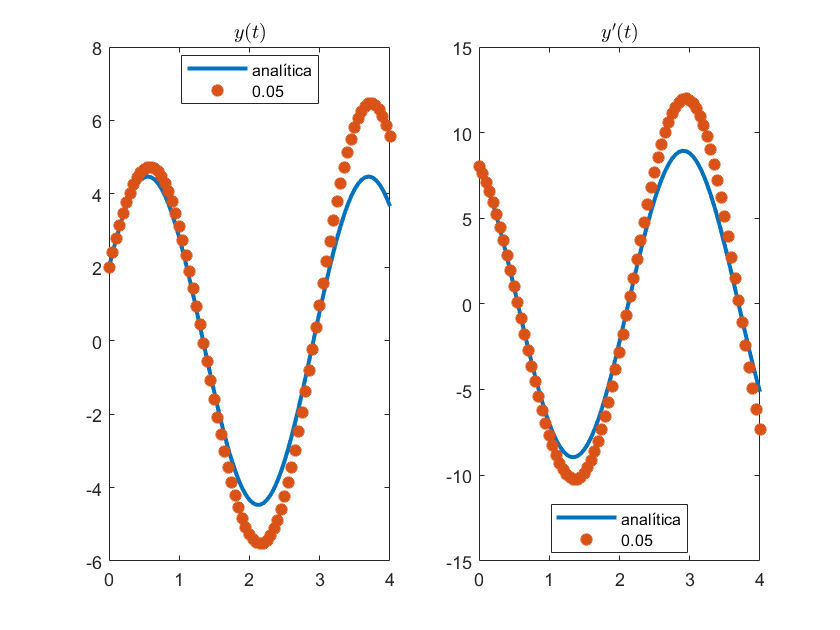

[t,YE] = EulerV(@edos,0,4,0.05,[2; 8]);
 
subplot(121),plot(t,Y(t),t,YE(:,1),'*','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(t,Z(t),t,YE(:,2),'*','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')

## `Solucions aproximades numèricament O(h^2)`

- `Mètode ode23`

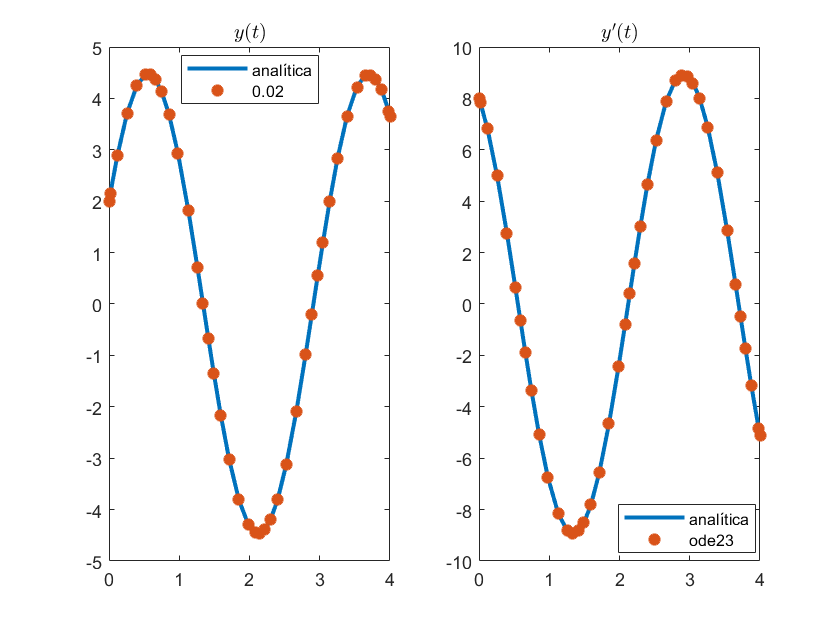

 [t,y] = ode23(@edos,[0 4],[2; 8]);
 
 % Gràfics
clf,figure(1)
subplot(121),plot(t,Y(t),t,y(:,1),'*','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(t,Z(t),t,y(:,2),'*','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica','ode23','Location','best')

function dydt = edos(t,y)
% 
    dydt = [y(2); -4*y(1)];
end
%---------------------------------------
%---------------------------------------
function [t, w ] = EulerV( f,a,b,h,alpha )
% Mètode d'Euler
% f una funcion @algo que retorna un vector columna [y1; y2; ...]
t=[a:h:b];
N=length(t);
w(1,:)=alpha;
    for i=1:N-1
        w(i+1,:)=w(i,:)+h*f(t(i),w(i,:))';
    end
end
%%%%